## Lab 3

    This lab focusses on asking a statistical question and then performing the appropriate analyses. There are three different problems that we will do this for. 

### Problem 1

We have temperature readings (metadata) associated with a particular experiment. For the experiment to work reliably, we need the temperature to be around 12K. The data is mostly within 12$\pm$0.4K. We want to identify and throw out data when the thermal control system and the thermometry were not working properly. We simulate 100k random 'good' data points below (thermometry fluctuations where we know the thermal control system was working properly), and add to that a few known 'bad' data points.

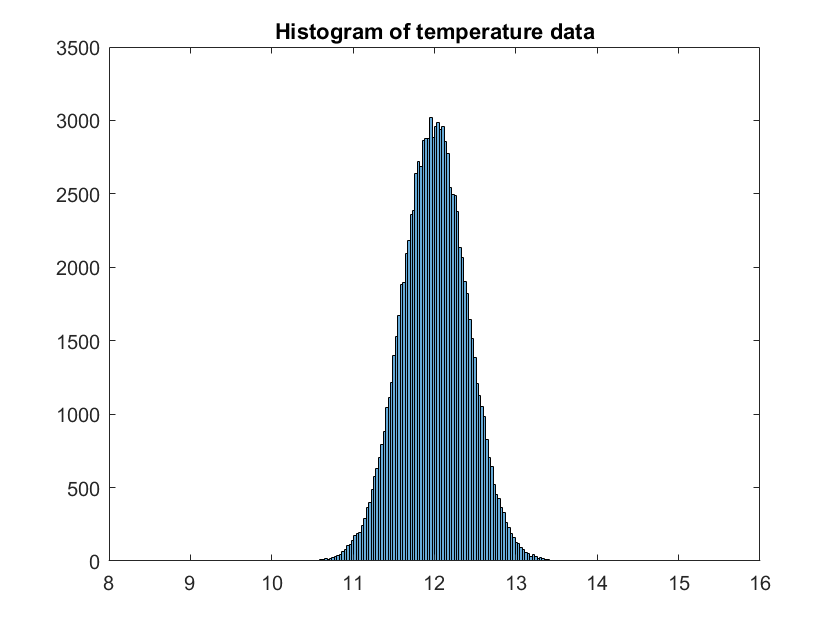

clear all; close all; clc
rng('default');
rng(1);
mu = 12;
sd = 0.4;
good = sd.*randn(1e5,1)+mu;
bad = [10.;10.3;2.1;0.;0.;15.6;22.3;12.7];
data1 = [good; bad];
histogram(data1)
xlim([8 16])
title('Histogram of temperature data')

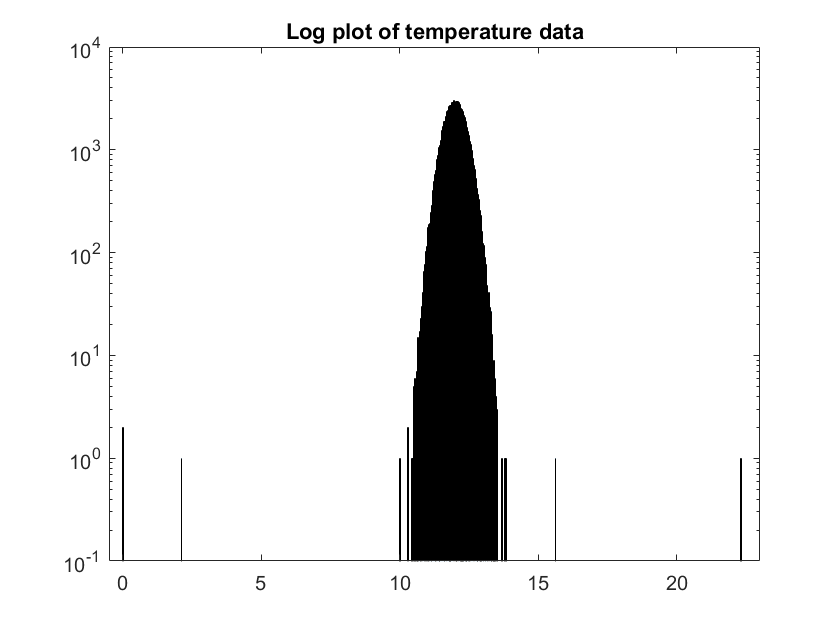

% hold on
% x = [8:0.1:16];
% y = 3000*normpdf(x,mu,sd);
% plot(x,y,'LineWidth',2)
% hold off
figure
histogram(data1)
set(gca,'YScale','log')
xlim([-0.5 23])
ylim([1e-1 1e4])
title('Log plot of temperature data')

The data appears to fit nicely into a Gaussian curve in the upper plot, but the outliers are obvious in the lower one. Given the goal of identifying bad data and throwing it out, we want to create a criteria for what we would consider bad data. Knowing that we have 8 bad data points out of 100,008 total data points, the probability that we choose a bad data point is

$P\left(\mathrm{bad}\right)=\frac{8}{100,008}=7\ldotp 9994\times {10}^{-5}$.

It is therefore reasonable to say that we want to discard $7\ldotp 9994\times {10}^{-5}$ of the data. It is also reasonable to assume that the bad data points are at the tails of the distribution since we would expect a bad reading to be an outlier far away from the mean. In light of this, we want to discard $7\ldotp 9994\times {10}^{-5}$ from the tails of our distribution. Exploiting the symmetry of our distribution (ie. the outliers occur on both sides of the distribution), we can simply halve the probability and discard this from one of the tails. Our aim now is to convert this threshold probability $P_T$ to a threshold sigma value $\sigma_T$ and subsequently an x-offset $x_T$ on our distribution. We reflect $x_T$ about the mean to find the threshold on the other tail. We then want to know how well our statistical threshold did.

Statistical Question

Given a Gaussian distribution of good data points with mean 12 and standard deviation 0.4, what is the probability that we discard good points (omission) and keep bad points (commission) for a statistical threshold $\sigma_T$.

Math Question


$$P\left(\mathrm{omission}\right)=\frac{n\left(\mathrm{good}\;\mathrm{points}\;\mathrm{excluded}\right)}{n\left(\mathrm{total}\;\mathrm{points}\right)}$$



$$P\left(\mathrm{commission}\right)=\frac{n\left(\mathrm{bad}\;\mathrm{points}\;\mathrm{included}\right)}{n\left(\mathrm{total}\;\mathrm{points}\right)}$$


To find $\sigma_T$, we solve for it in the equation

$\int_{\sigma_T \;}^{\infty } \frac{1}{\sqrt{\;2\pi }}e^{-x^2 /2} =P_T ,\;P_T =3\ldotp 9997\times {10}^{-5}$.

To find $x_T$, we use the same probability $P_T$ and solve for $x_T$ in the equation

$\int_{12+x_T }^{\infty } \frac{1}{0\ldotp 4\sqrt{\;2\pi }}e^{-{\left(x-12\right)}^2 /\left(2\left(0\ldotp 4^2 \right)\right)} =P_T$.

Once we have $x_T$, we can evaluate our simulated data to see how many good points we throw out and how many bad points we keep.

% Solve for sigma
Pt = 3.9997e-5;
sigt = norminv(1-Pt);
% solve for xt
xt = norminv(1-Pt,mu,sd)-12;


$$\begin{array}{l}
\sigma_T =3\ldotp 9444\\
x_T =1\ldotp 5778
\end{array}$$


Note that for a Gaussian distribution, we can simply take $\sigma_T \cdot \left(\mathrm{standard}\;\mathrm{deviation}\right)$ to find $x_T \ldotp$The bounds we want to impose on the good data are 12$\pm$1.5778. Everything outside these bounds will be discarded. Below we look through the list of good data points and pick out those that fall outside the bounds.

low = [];
high = [];
for j=1:length(good)
    temp = good(j);
    if temp<mu-xt
        % add to low
        low = [low temp];
    elseif temp>mu+xt
        % add to high
        high = [high temp];
    end
end

We also look at the list of bad data points and identify those that are within the bounds. The results are summarized in the truth table below.

With a threshold sigma $\sigma_T$ of 3.9444 and threshold x-offset of 1.5778 from the mean, we have

$P\left(\mathrm{omission}\right)=\frac{4}{100,008}=3\ldotp 9997\times {10}^{-5}$,

$P\left(\mathrm{commission}\right)=\frac{1}{100,008}=9\ldotp 9992\times {10}^{-6}$.

It was very effective in preventing false positives, but based on our knowledge of the what the good data is, could be improved to eliminate the true negatives.

We explore this further by first looking at how adjusting $\sigma_T$ changes the number of omissions. We test it over a range from $\sigma_T =3$ to $\sigma_T =5$ in steps of 0.1.

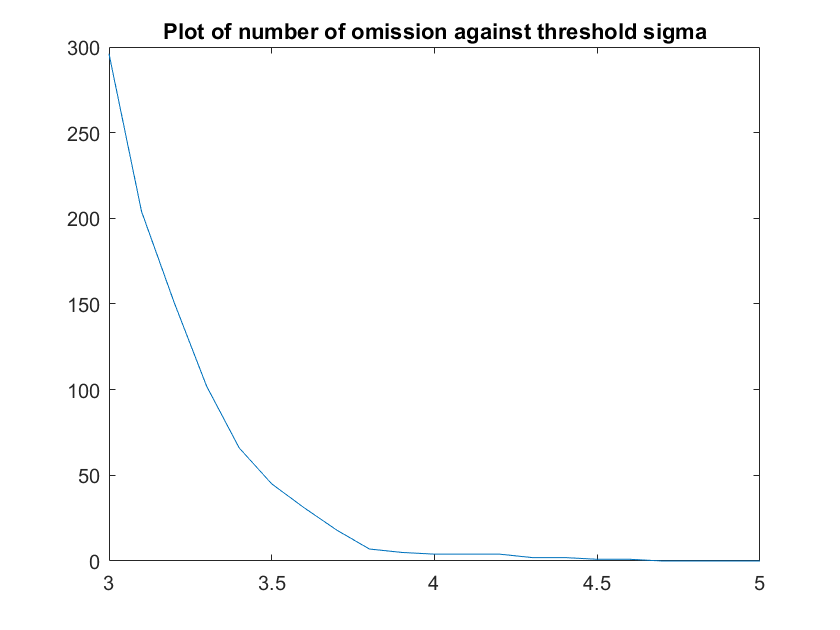

sig_test = 3:0.1:5;
count = zeros(1,length(sig_test));
for k=1:length(sig_test)
    omit = [];
    sig = sig_test(k);
    % compute x_test
    p_test = 1-normcdf(sig);
    x_test = norminv(1-p_test,mu,sd)-12;
    for j=1:length(good)
        temp = good(j);
        if temp<mu-x_test
            % add to omit
            omit = [omit temp];
        elseif temp>mu+x_test
            % add to omit
            omit = [omit temp];
        end
    end
    count(k) = length(omit);
end
plot(sig_test,count)
title('Plot of number of omission against threshold sigma')

The plot above shows that there is a relationship between the threshold sigma and the number of omissions. It follows the shape of the Gaussian tail, which makes sense because as we increase $\sigma_T$ linearly, we move further away from the mean at a constant rate so the decrease in the number of points outside the bounds looks like the Gaussian. We can be fairly confident of decreasing the number of omissions by increasing $\sigma_T$.

As for mistakes of commission, there is 1 bad data point that got into our data set. This is unavoidable as it has a value of 12.7, only $\sigma =1\ldotp 75$ away from the mean. We cannot get rid of this data point without throwing out a significant amount of good data. As for the other bad data points, the values 10 and 10.3 may be falsely included if we increase $\sigma_T$ by a little bit. The others are outside the reasonable range of what we would increase it to. 15.6 is the next closest value, which is $\sigma =9$ away from the mean.

### Problem 2

We would like to look for an asteroid based on the difference in its position between subsequent images, and want a 5 sigma detection of movement. We are given a 2D Gaussian of positional uncertainty. The brightness of each pixel on the given histogram corresponds to a likelihood of finding stars that have moved by the coordinates ($\Delta x$ and $\Delta y$) of the pixel. We can use Pythagoras' theorem to convert this 2D distribution into a 1D parameterization

$r=\sqrt{\left(\Delta x{\left.\right)}^2 +{\left(\Delta y\right)}^2 \right.}$.

The result is a Rayleigh distribution. Since the 2D distribution had an RMS of 1 arcsecond, the Rayleigh distribution now has a mean of 1.


$$\mathrm{RMS}=$$


Statistical Question

Given a background distribution normally distributed in x and y, what is the probability that the background gives me 

Convert 2d normal distribution to 1d rayleigh distribution with parameter r in arcseconds.

The question: 